
load short_modem_rx.mat

% The received signal includes a bunch of samples from before the
% transmission started so we need discard these samples that occurred before
% the transmission started. 

start_idx = find_start_of_signal(y_r,x_sync);

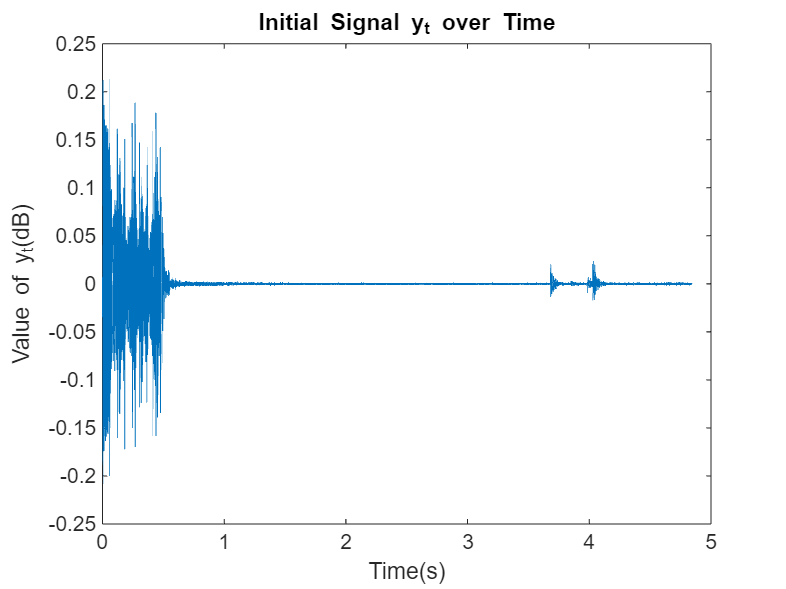

% start_idx now contains the location in y_r where x_sync begins
% we need to offset by the length of x_sync to only include the signal
% we are interested in
y_t = y_r(start_idx+length(x_sync):end); % y_t is the signal which starts at the beginning of the transmission


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%  Put your decoder code here
t = (0:length(y_t)-1)'/Fs; 
plot(t, y_t)
title("Initial Signal y_t over Time")
xlabel("Time(s)")
ylabel("Value of y_t(dB)")

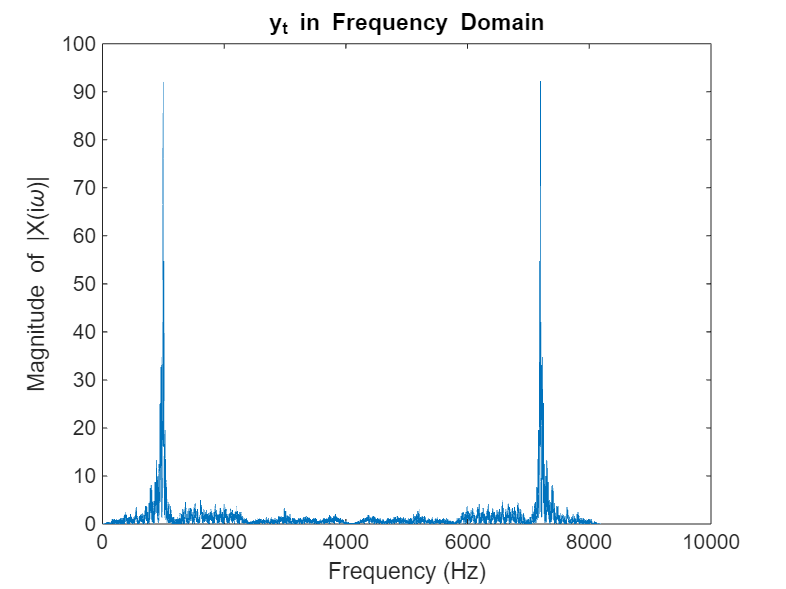

f = 1.0e+03 *

         0    0.0002    0.0004    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0019    0.0021    0.0023    0.0025    0.0027    0.0029    0.0031    0.0033    0.0035    0.0037    0.0039    0.0041    0.0043    0.0045    0.0048    0.0050    0.0052    0.0054    0.0056    0.0058    0.0060    0.0062    0.0064    0.0066    0.0068    0.0070    0.0072    0.0074    0.0076    0.0078    0.0081    0.0083    0.0085    0.0087    0.0089    0.0091    0.0093    0.0095    0.0097    0.0099    0.0101


X =   -0.0056 + 0.0000i
  -0.0075 - 0.0059i
  -0.0077 - 0.0055i
  -0.0102 - 0.0074i
  -0.0166 - 0.0060i
  -0.0204 - 0.0058i
  -0.0202 - 0.0016i
  -0.0189 + 0.0005i
  -0.0158 + 0.0033i
  -0.0115 + 0.0013i



[f, X] = make_frequency_domain_plot(Fs, y_t, "y_t")

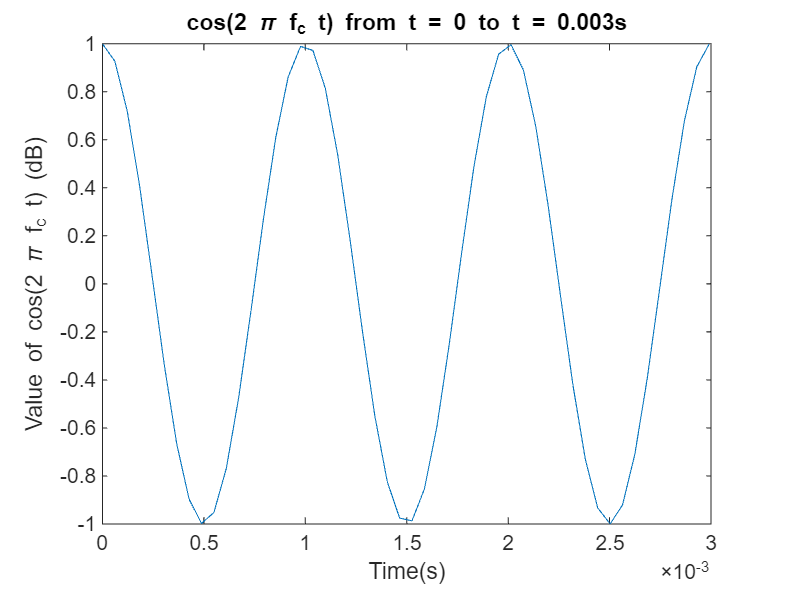


%% 
t_special = (0:length(y_t)-1)'/(Fs*2); 
cosinewave = cos(2*pi*f_c*t);
cosinewave_special = cos(2*pi*f_c*t_special);
plot(t_special(1:50), cosinewave_special(1:50))
title("cos(2 \pi f_c t) from t = 0 to t = 0.003s")
xlabel("Time(s)")
ylabel("Value of cos(2 \pi f_c t) (dB)")

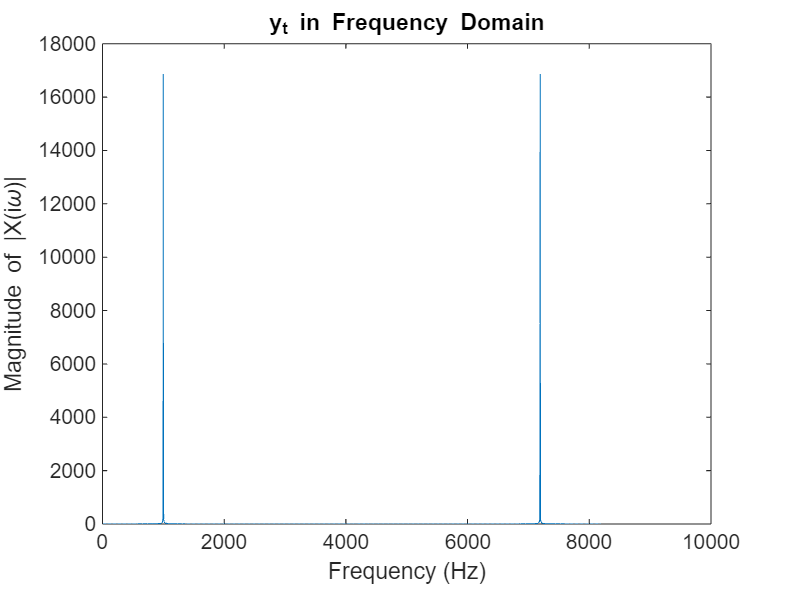

f = 1.0e+03 *

         0    0.0002    0.0004    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0019    0.0021    0.0023    0.0025    0.0027    0.0029    0.0031    0.0033    0.0035    0.0037    0.0039    0.0041    0.0043    0.0045    0.0048    0.0050    0.0052    0.0054    0.0056    0.0058    0.0060    0.0062    0.0064    0.0066    0.0068    0.0070    0.0072    0.0074    0.0076    0.0078    0.0081    0.0083    0.0085    0.0087    0.0089    0.0091    0.0093    0.0095    0.0097    0.0099    0.0101


X = 1.0e+04 *

   0.0002 + 0.0000i
   0.0002 + 0.0000i
   0.0002 + 0.0000i
   0.0002 + 0.0000i
   0.0002 + 0.0000i
   0.0002 + 0.0000i
   0.0002 + 0.0000i
   0.0002 + 0.0000i
   0.0002 + 0.0000i
   0.0002 + 0.0000i




[f, X] = make_frequency_domain_plot(Fs, cosinewave, "y_t")

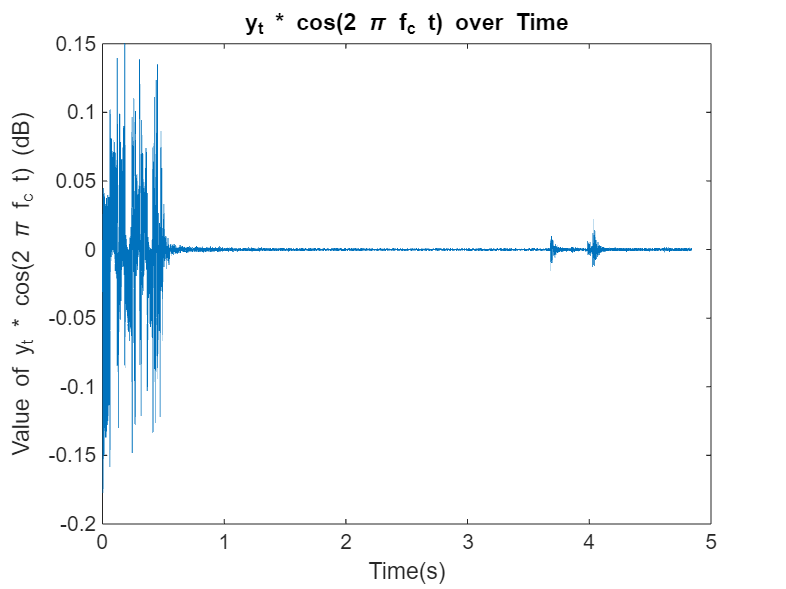

%% 

x_d = y_t .* cosinewave; 
plot(t, x_d)
title("y_t * cos(2 \pi f_c t) over Time")
xlabel("Time(s)")
ylabel("Value of y_t * cos(2 \pi f_c t) (dB)")

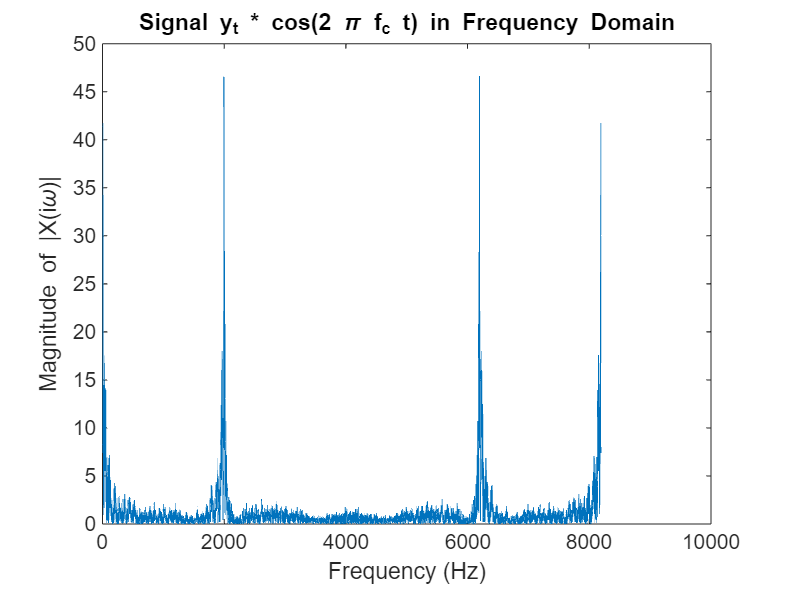

f = 1.0e+03 *

         0    0.0002    0.0004    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0019    0.0021    0.0023    0.0025    0.0027    0.0029    0.0031    0.0033    0.0035    0.0037    0.0039    0.0041    0.0043    0.0045    0.0048    0.0050    0.0052    0.0054    0.0056    0.0058    0.0060    0.0062    0.0064    0.0066    0.0068    0.0070    0.0072    0.0074    0.0076    0.0078    0.0081    0.0083    0.0085    0.0087    0.0089    0.0091    0.0093    0.0095    0.0097    0.0099    0.0101


X =   -8.2368 + 0.0000i
  -7.9817 + 0.0520i
  -7.5773 - 0.4026i
  -7.2463 - 1.6702i
  -7.2138 - 3.4733i
  -7.7711 - 5.2865i
  -9.2641 - 6.7404i
 -11.6970 - 7.3140i
 -14.6319 - 7.0141i
 -16.9714 - 5.7514i


[f, X] = make_frequency_domain_plot(Fs, x_d, "Signal y_t * cos(2 \pi f_c t)")

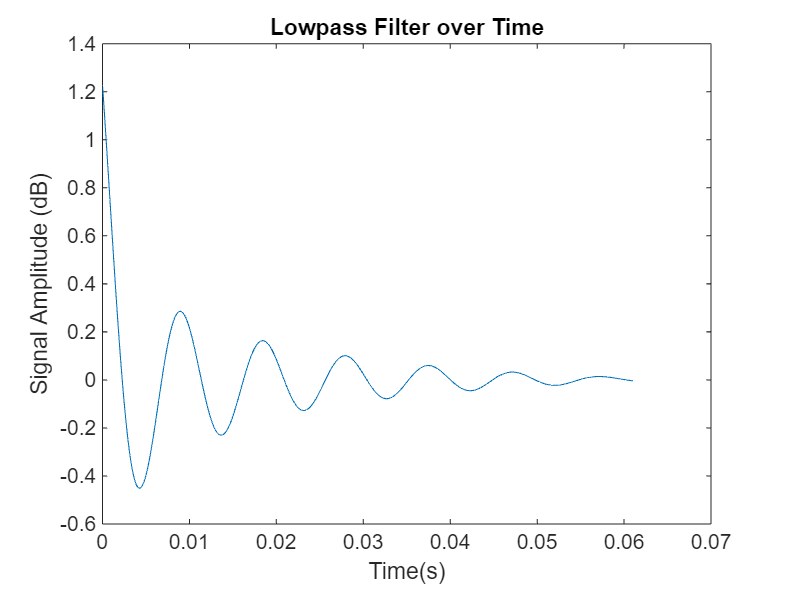

%% 

x_d_fil = lowpass(x_d,100,Fs,'Steepness',0.99);
%% 

lowpass_filter = lowpass([1 ; zeros([500 1])],100,Fs,'Steepness',0.99);
t_sp = (0:length(lowpass_filter)-1)'/Fs;
plot(t_sp, lowpass_filter)
title("Lowpass Filter over Time")
xlabel("Time(s)")
ylabel("Signal Amplitude (dB)")

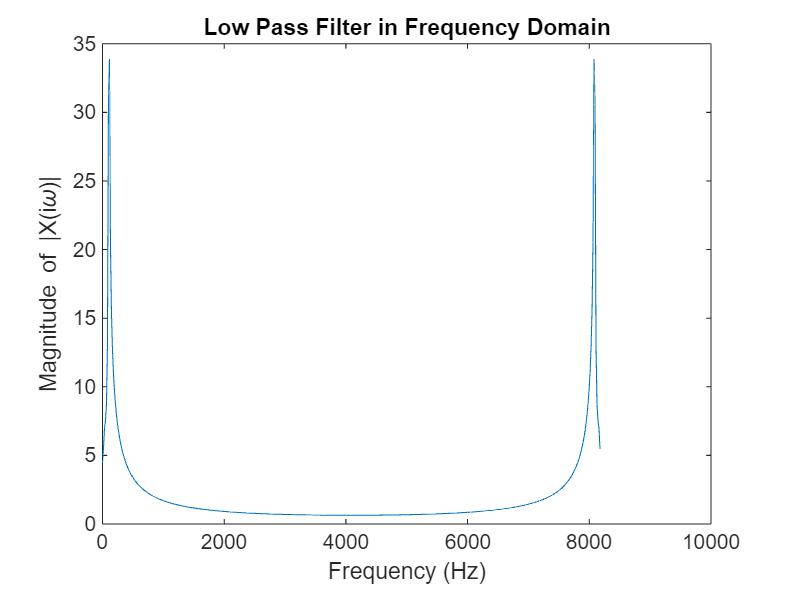

f = 1.0e+03 *

         0    0.0164    0.0327    0.0491    0.0654    0.0818    0.0981    0.1145    0.1308    0.1472    0.1635    0.1799    0.1962    0.2126    0.2289    0.2453    0.2616    0.2780    0.2943    0.3107    0.3270    0.3434    0.3597    0.3761    0.3924    0.4088    0.4251    0.4415    0.4578    0.4742    0.4905    0.5069    0.5232    0.5396    0.5559    0.5723    0.5886    0.6050    0.6213    0.6377    0.6541    0.6704    0.6868    0.7031    0.7195    0.7358    0.7522    0.7685    0.7849    0.8012


X =    4.4670 + 0.0000i
   5.1561 + 1.8288i
   6.4155 + 2.5888i
   6.8853 + 2.9889i
   7.2420 + 4.8816i
   9.6503 + 8.6627i
  24.3339 +18.5341i
  28.9283 -17.6036i
  12.9511 -15.9166i
   8.3505 -13.0928i




[f, X] = make_frequency_domain_plot(Fs, lowpass_filter, "Low Pass Filter")

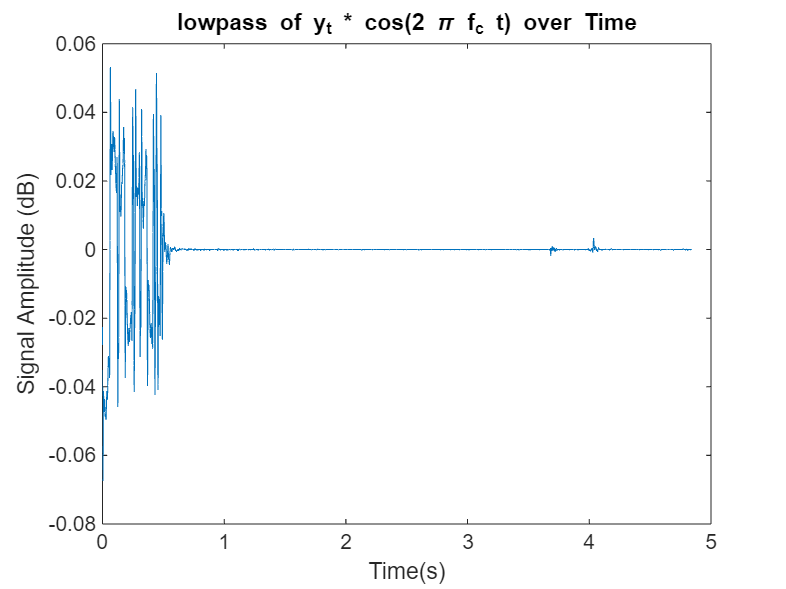

%% 

plot(t, x_d_fil)
title("lowpass of y_t * cos(2 \pi f_c t) over Time")
xlabel("Time(s)")
ylabel("Signal Amplitude (dB)")

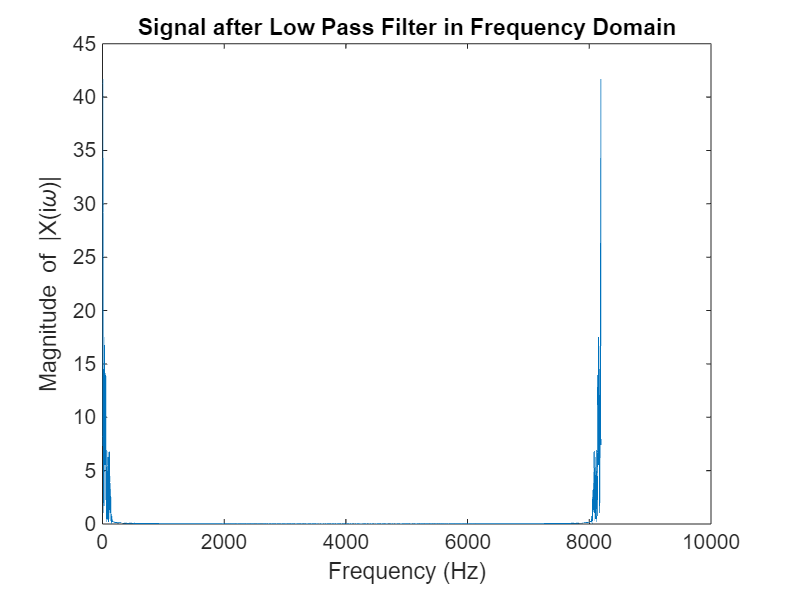

f = 1.0e+03 *

         0    0.0002    0.0004    0.0006    0.0008    0.0010    0.0012    0.0014    0.0017    0.0019    0.0021    0.0023    0.0025    0.0027    0.0029    0.0031    0.0033    0.0035    0.0037    0.0039    0.0041    0.0043    0.0045    0.0048    0.0050    0.0052    0.0054    0.0056    0.0058    0.0060    0.0062    0.0064    0.0066    0.0068    0.0070    0.0072    0.0074    0.0076    0.0078    0.0081    0.0083    0.0085    0.0087    0.0089    0.0091    0.0093    0.0095    0.0097    0.0099    0.0101


X =   -8.1833 + 0.0000i
  -7.9283 + 0.0518i
  -7.5238 - 0.4028i
  -7.1928 - 1.6706i
  -7.1603 - 3.4738i
  -7.7177 - 5.2872i
  -9.2107 - 6.7413i
 -11.6437 - 7.3151i
 -14.5786 - 7.0153i
 -16.9182 - 5.7527i




[f, X] = make_frequency_domain_plot(Fs, x_d_fil, "Signal after Low Pass Filter")

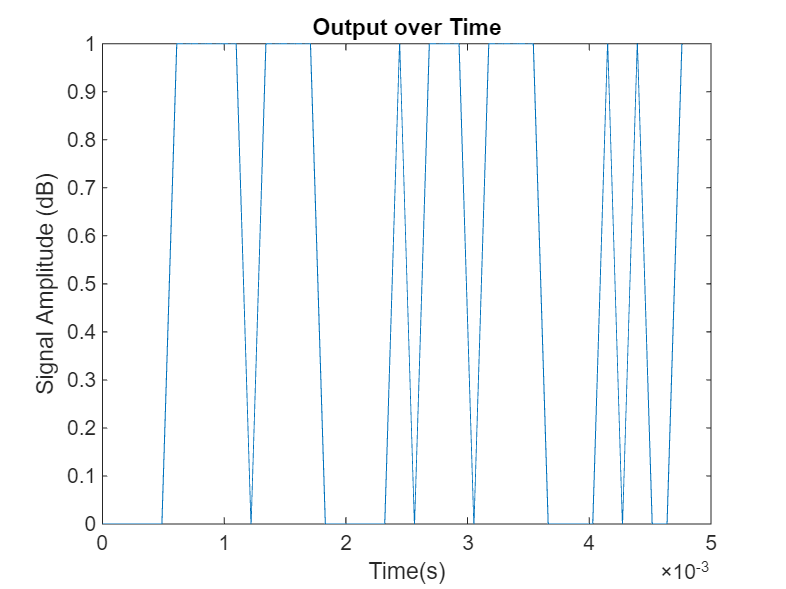

per = 100; 

mid_idx = (per/2):per:length(x_d_fil); % middle of each bit
s_vals = x_d_fil(mid_idx); % sampled values/bit
d_bit = s_vals > 0; % pos is 1 neg is 0

tot_bits = msg_length*8; % total bits

x_d = d_bit(1:tot_bits); % cut off extra bits at the end
t = (0:length(x_d)-1)'/Fs;
plot(t, x_d)
title("Output over Time")
xlabel("Time(s)")
ylabel("Signal Amplitude (dB)")

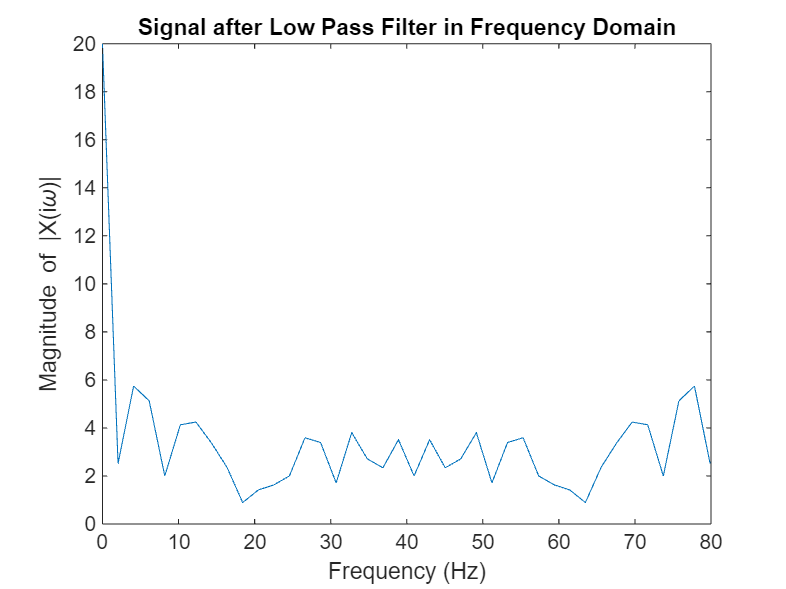

f =          0    2.0480    4.0960    6.1440    8.1920   10.2400   12.2880   14.3360   16.3840   18.4320   20.4800   22.5280   24.5760   26.6240   28.6720   30.7200   32.7680   34.8160   36.8640   38.9120   40.9600   43.0080   45.0560   47.1040   49.1520   51.2000   53.2480   55.2960   57.3440   59.3920   61.4400   63.4880   65.5360   67.5840   69.6320   71.6800   73.7280   75.7760   77.8240   79.8720


X =   20.0000 + 0.0000i
  -2.0667 - 1.4418i
  -4.3138 - 3.7936i
   0.6904 + 5.0809i
  -1.6180 + 1.1756i
  -2.7071 + 3.1213i
   3.9626 - 1.5201i
   3.2802 - 0.7729i
  -1.3820 + 1.9021i
   0.8629 - 0.2284i



[f, X] = make_frequency_domain_plot(Fs/100, x_d, "Signal after Low Pass Filter")

%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% convert to a string assuming that x_d is a vector of 1s and 0s
% representing the decoded bits.
BitsToString(x_d)

ans = 'Hello'


function [f, X] = make_frequency_domain_plot(Fs, x, Algorithm)
    N = length(x);
    t = (1:1:N)/Fs;
    X = fft(x);
    f = (0:N-1)*(Fs/N);
    plot(f, abs(X))
    xlabel('Frequency (Hz)')
    ylabel('Magnitude of |X(i\omega)|')
    title(Algorithm + ' in Frequency Domain')
end